% MATLAB Code for Root Locus Analysis of the Uncompensated System
% ---------------------------------------------------------------
% This script defines the open-loop transfer function of the robotic arm joint
% and generates its Root Locus plot to analyze stability as gain varies.

% Clear workspace, command window, and close all figures for a clean run
clear;
clc;
close all;

% --- 1. Define the System ---
% Define the numerator and denominator of the open-loop transfer function G_ol(s).
% G_ol(s) = -10.07 / (s^2 + 1806s + 4843)
num_ol = [-10.07];       % Numerator coefficients
den_ol = [1, 1806, 4843]; % Denominator coefficients

% Create the transfer function object for the open-loop system.
G_ol = tf(num_ol, den_ol);

% Display the transfer function in the command window to verify.
disp('Open-Loop Transfer Function (G_ol):');

Open-Loop Transfer Function (G_ol):


G_ol


G_ol =
 
        -10.07
  -------------------
  s^2 + 1806 s + 4843
 
Continuous-time transfer function.
Model Properties


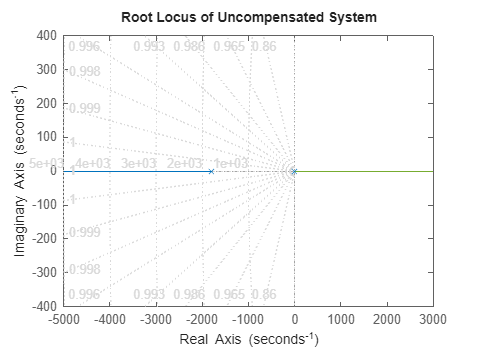


% --- 2. Generate and Display the Root Locus Plot ---
% Create a new figure window for the plot.
figure;

% Generate the Root Locus plot for the open-loop system.
% The rlocus command calculates and plots the paths of the closed-loop poles
% as the system gain (K) varies from 0 to infinity.
rlocus(G_ol);

% --- 3. Enhance the Plot for Reporting ---
% Add a title to the plot.
title('Root Locus of Uncompensated System');

% Add a grid for better readability of pole locations.
grid on;

% Add labels to the x and y axes.
xlabel('Real Axis');
ylabel('Imaginary Axis');


% The plot will automatically show the starting points (poles of G_ol, marked 'x')
% and end points (zeros of G_ol, marked 'o'). In this case, there are no finite
% zeros, so the loci will go to infinity along the real axis.

